## TranslationImageRegistrationUsingPhaseCorrelation

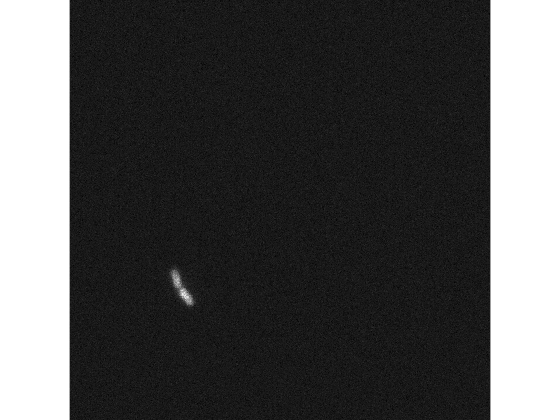

%https://thilinasameera.wordpress.com/2012/03/24/translation-invariant-image-registration-using-phase-correlation-panorama-imaging-on-matlab/

% hanning1D_row = hanning(image_width);
% hanning1D_col = hanning(image_height);
% hanning2D = hanning1D_row*hanning1D_col;
% % Then the hanning window is multiplied in element-wise with two images for obtaining edge effect reduced images.
% 
% 
% image_left_flt = hanning2D.*image_left;
% image_right_flt = hanning2D.*image_right;
% % The 2D Fast Fourier Transform is applied to these edge effect reduced images. And they are used to obtain Cross Power Spectrum of images.
% 
% 
% FFT_L = fft2(image_left_flt );
% FFT_R = fft2(image_right_flt );
% IMF = FFT_L*.conj(FFT_R);
% CPS = IMF./abs(IMF);
% Code for this process is as below.


clc;
% clear all;
% close all;
im01 = CyOFP_10001;%imread('image_01.jpg');
im02 = CyOFP_10002;%imread('image_02.jpg');
im01 = rescale(double(im01))*255;
im02 = rescale(double(im02))*255;
im1 = im01;
im2 = im02;
 
F1 = fftshift(fft2(im1));
F2 = fftshift(fft2(im2));
 
[r1, c1, d1] = size(im1);
[r2, c2, d2] = size(im2);
 
F = F1.*conj(F2);
F = F./abs(F);
mag = (ifft2(F));
 
[X, Y] = find((mag == (max(max(mag)))));
 
if im1(1,1)==im2(end-X,end-Y)
    img = zeros(r2-X+r1,c2-Y+c1,1);
    img=cast(img,'uint8');
    img(1:r2,1:c2,:)=im02;
    img(r2-X:r2-X+r1-1,c2-Y:c2-Y+c1-1,:)=im01;
else
    img = zeros(X+r2-1,Y+c2,1);
    img=cast(img,'uint8');
    img(1:r1,1:c1,:)=im01;
    img(X:X+r2-1,Y:Y+c2-1,:)=im02;
end
 
img=cast(img,'uint8');
imshow(img);

imout = imcrop(img);